Class 1: iTAML\cifar10\iTAML_ses_0_XA_dcts.mat


Class 2: iTAML\cifar10\iTAML_ses_4_XA_dcts.mat



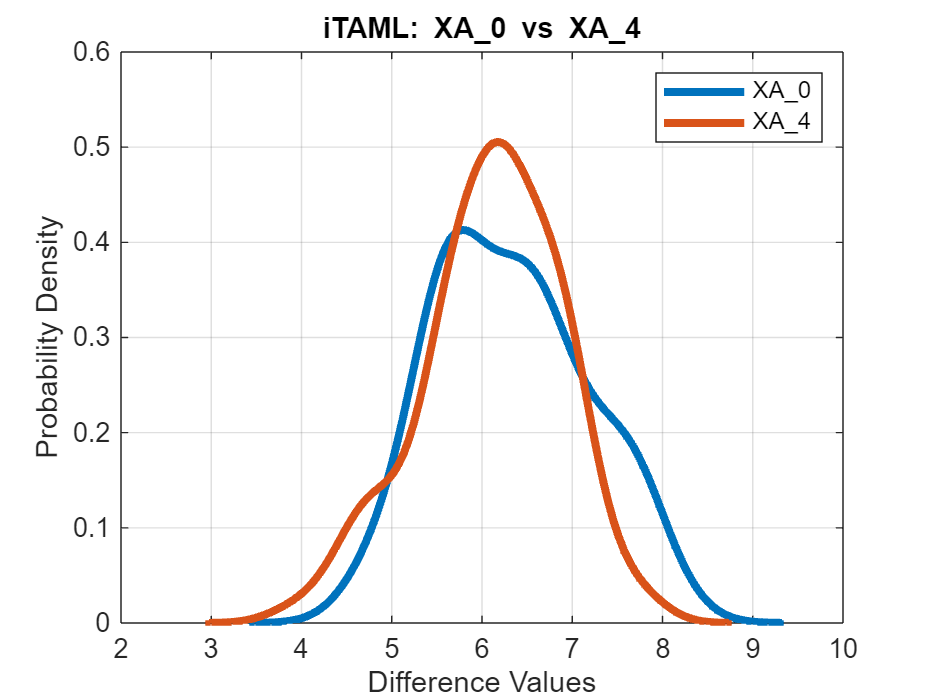

Class 1: iTAML\cifar10\iTAML_ses_0_XA_dcts.mat


Class 2: iTAML\cifar10\iTAML_ses_0_XB_dcts.mat



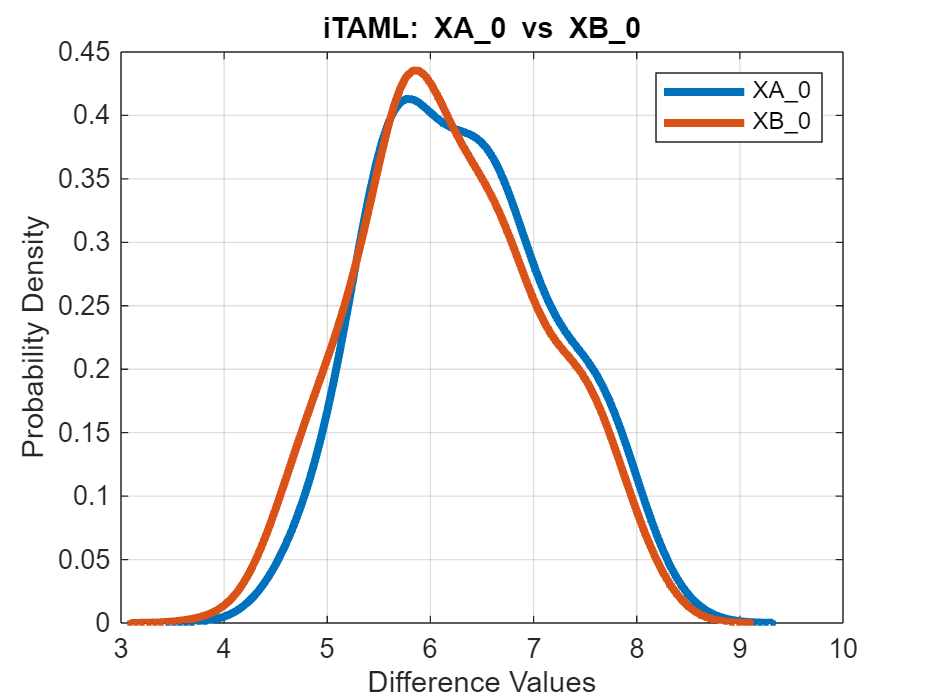

% Generate All PDFs

alg = "iTAML";
dataset = 'cifar10';

paths = {{'ses_0_XA_dcts.mat','ses_4_XA_dcts.mat'},
         {'ses_0_XA_dcts.mat','ses_0_XB_dcts.mat'}};

%paths = {{'ses_0_XA_dcts.mat','ses_9_XA_dcts.mat'},
%         {'ses_0_XA_dcts.mat','ses_0_XB_dcts.mat'}};

titles = ["XA\_0 vs XA\_4", "XA\_0 vs XB\_0", "XA\_4 vs XB\_4"];


for i=1:length(paths)

    class1 = load(sprintf("%s\\%s\\%s_%s", alg, dataset, alg, paths{i}{1}));
    fprintf('Class 1: %s\n', sprintf("%s\\%s\\%s_%s", alg, dataset, alg, paths{i}{1}))
    fns = fieldnames(class1);
    data1 = class1.(fns{1});    
    p1=gkdeb(data1);
    
    class2 = load(sprintf("%s\\%s\\%s_%s", alg, dataset, alg, paths{i}{2}));
    fprintf('Class 2: %s\n\n', sprintf("%s\\%s\\%s_%s", alg, dataset, alg, paths{i}{2}))
    fns = fieldnames(class2);
    data2 = class2.(fns{1});
    p2=gkdeb(data2);

    % Plot both PDFs
    fig = figure;
    
    % Plot the PDF
    plot(p1.x, p1.pdf, '.-', 'LineWidth', 3);
    title(sprintf("%s: %s", alg, titles(i)));
    xlabel('Difference Values');
    ylabel('Probability Density');
    hold on;
    
    % Plot the PDF
    plot(p2.x, p2.pdf, '.-', 'LineWidth', 3);
    hold off;
    
    %legend('In-Class', 'Out-of-Class');
    legend_names = split(titles(i));
    legend(legend_names(1), legend_names(3));
    grid on;

    %copygraphics(fig); % Copy the figure to the clipboard
    % Wait until the figure is closed
    %uiwait(fig);
end